
% figure R v.s. Density Ratio %

clear all;
close all;

load('E:\Data\2024-11-26\R_vs_density_ratio.mat');

wx = 1./err_x.^2;
wx12 = [wx(1) wx(2)];
x12 = [x(1) x(2)];
new_x = sum(wx12.*x12) / sum(wx12);
new_err_x = 8.8/5*err_x(4);
%new_err_x = (err_x(1)^1+err_x(2)^1+sqrt(sum(wx12.*(x12-new_x).^2)/sum(wx12)));
%new_err_x = sqrt( (sum(wx12.*(x12-new_x).^2) + 2) / sum(wx12) );


x(1) = new_x; err_x(1) = new_err_x;
x(2) = []; err_x(2) = [];

ytemp = [0.726072 0.726082 0.726070 0.726062];
eytemp = [3 4 4 5]*1e-6;
wytemp = 1./eytemp.^2;
new_y = sum(ytemp.*wytemp)/sum(wytemp);
new_err_y = sqrt(sum(wytemp.*(ytemp-new_y).^2+1) / sum(wytemp));


% wy12 = w1(1:2);
% y12 = y1(1:2);
% new_y = sum(wy12.*y12) / sum(wy12);
% new_err_y = sqrt( sum( wy12.*((y12-new_y).^2+1./wy12) ) / sum(wy12) );
y1(1) = new_y; err1(1) = new_err_y;
y1(2) = []; err1(2) = [];
w1 = 1./err1.^2;

y_mean1 = sum(w1.*y1)/sum(w1);
err_mean1 = sqrt( sum( w1.*((y1-y_mean1).^2+1./w1) ) / sum(w1) );


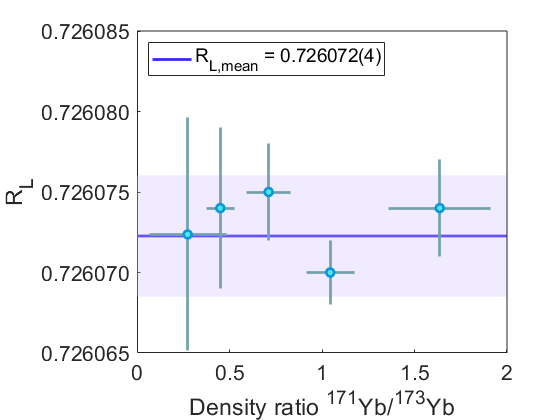


x_low = 0;
x_high = 2;

f1 = figure; hold on;

plot([x_low x_high],[y_mean1 y_mean1],Color=[0.22 0.14 1],LineWidth=2);
n1 = [1 2 3 4];
patch_list = [x_low y_mean1-err_mean1;x_high y_mean1-err_mean1;x_high y_mean1+err_mean1;x_low y_mean1+err_mean1];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');

E1 = errorbar(x,y1,err1,err1,err_x,err_x,'o', LineWidth=2, MarkerSize=6);

E1.CapSize = 0;
E1.MarkerEdgeColor = [0.04,0.59,0.83];
E1.MarkerFaceColor = [0.29,0.91,0.91];
E1.Color = [0.45,0.63,0.67];

set(gca,'FontSize',16,'FontName','arial','FontWeight','normal',...
    'YScale','linear','XScale','linear');

x_low = 0;
x_high = 2;
y_low = 0.726065;
y_high = 0.726085;

xlim([x_low,x_high]);
ylim([y_low,y_high]);
yticks([0.726065:5e-6:0.726085]);
yticklabels({'0.726065','0.726070','0.726075','0.726080','0.726085'});
grid off;
box off;

plot([x_low x_high],[y_high y_high],'Color',[0.15 0.15 0.15]);
plot([x_high x_high],[y_low y_high],'Color',[0.15 0.15 0.15]);

xlabel('Density ratio ^{171}Yb/^{173}Yb');
ylabel('R_L');

legend(['R_{L,mean} = ',num2str(roundn(y_mean1,-6),'%.6f'),'(',num2str(round(err_mean1*1e6)),')'],'','', ...
    'Location','northwest','FontSize',14);

hold off;

set(f1,'Visible','on');


savefig(f1,'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig3\RvsDensity1.fig');
%saveas(f1,'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig3\RvsDensity.png');
%saveas(f1,'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig3\RvsDensity.eps','psc');

save('D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig3\RvsDensity1.mat');
